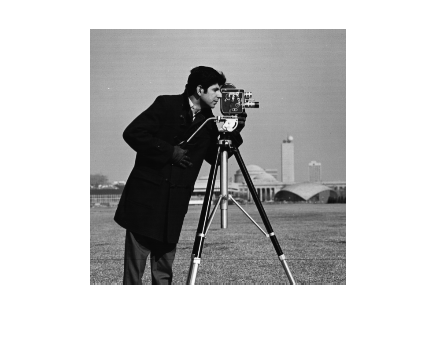

cman=imread("cameraman.tif");
coins=imread("coins.png");
imshow(cman)

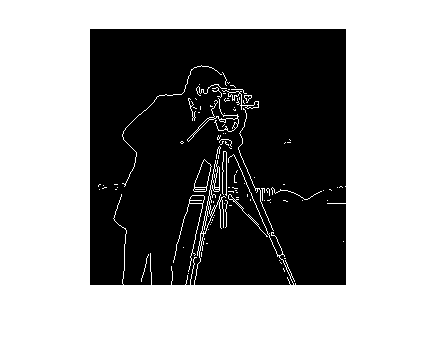

cman_out=edge(cman,"sobel");
coins_out=edge(coins,"sobel");
imshow(cman_out)

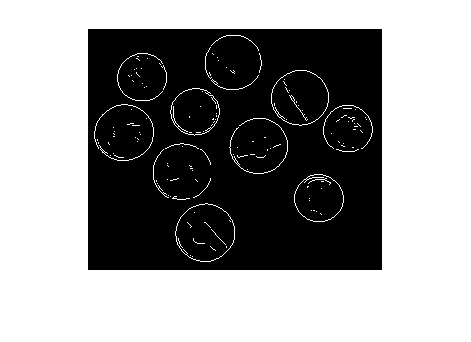

imshow(coins_out)

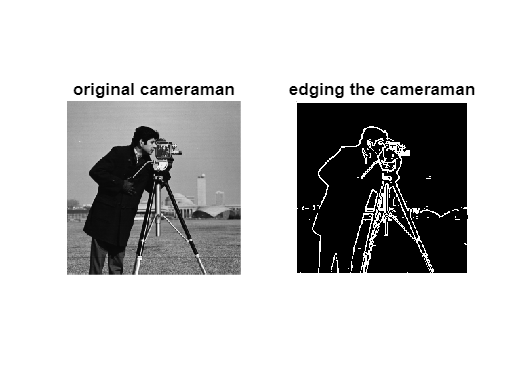

%for cameraman
x_mask = [-1 -2 -1; 0 0 0; 1 2 1]; 
y_mask = [-1 0 1; -2 0 2; -1 0 1];
x_cman=conv2(cman,x_mask);
y_cman=conv2(cman,y_mask);
result=sqrt(x_cman.^2 + y_cman.^2);

for i=1:1:257
    for j=1:1:257
        if (result(i,j)>252)
            result(i,j)=255;
        else
            result(i,j)=0;
        end

    end
end
figure
subplot(1,2,1), imshow(cman), title("original cameraman");
subplot(1,2,2), imshow(result), title("edging the cameraman");

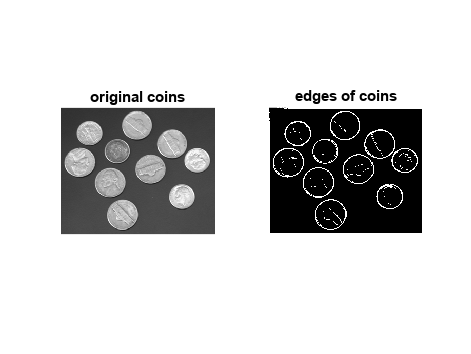

%for coins
x_mask = [-1 -2 -1; 0 0 0; 1 2 1]; 
y_mask = [-1 0 1; -2 0 2; -1 0 1];
x_coins=conv2(coins,x_mask);
y_coins=conv2(coins,y_mask);
coins_res=sqrt(x_coins.^2 + y_coins.^2);
for i=1:1:247
    for j=1:1:301
        if (coins_res(i,j)>200)
            coins_res(i,j)=255;
        else
            coins_res(i,j)=0;
        end

    end
end
figure
subplot(1,2,1), imshow(coins), title("original coins");
subplot(1,2,2), imshow(coins_res), title("edges of coins");